Question 6) Controller Pole Placement

% Define reference values
Href = 0.3048 * 30000;  % 30,000 ft in meters
Mref = 0.6*343;         % Mach number

% Augment the system to include height h and mach number m
x6 = {'u', 'w', 'q', 'theta', 'h'};
y6 = {'mach number', 'height'};

A_a = zeros(5,5);
A_a(1:4,1:4) = a1;
A_a(5,1:4) = [0, 1, 0, 0]; % dh/dt = y velocity
B_a = [b1; [0 0]]; % Approximation
C_a = [0 0 0 1 0; 1 0 0 0 0];

sys_mimo6 = ss(A_a,B_a,C_a,zeros(2,2),'statename',x6,...
'inputname',u1,...
'outputname',y6);

rank(ctrb(sys_mimo6))

ans = 5

rank(obsv(sys_mimo6))

ans = 4

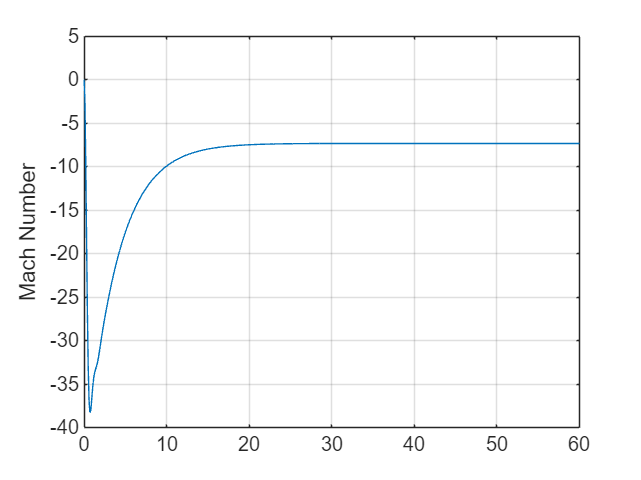


wn = 5;
Eig5 = roots([1, 2.8*wn, 5*wn^2, 5.5*wn^3, 3.4*wn^4, 1*wn^5]); 
K = place(A_a, B_a, Eig5);

A_pl = A_a - B_a*K;
B_pl = B_a;   
C_pl = C_a;
sys_pl = ss(A_pl, B_pl, C_pl, zeros(2,2),'statename',x6,...
'inputname',u1,...
'outputname',y6);

% Lag Times
tMM = .05;
tTS = 5;
tES = .02;
tA = .8;

% Input 1 lag: .2 / (s+.2)
A1 = -1/tTS; B1 = 1; C1 = 1/tTS; D1 = 0;
G1 = ss(A1, B1, C1, D1);

% Input 2 lag: 50 / (s+50)
A2 = -1/tES; B2 = 1; C2 = 1/tES; D2 = 0;
G2 = ss(A2, B2, C2, D2);

% Combine into diagonal (MIMO) system
G1.StateName = {'lag_mach'};
G2.StateName = {'lag_height'};
lag_block = blkdiag(G1, G2);

sys_forward = series(lag_block, sys_pl);

% Feedback lag 1: H(s) = 20 / (s + 20)
A_f1 = -1/tMM; B_f1 = 1; C_f1 = 1/tMM; D_f1 = 0;
H1= ss(A_f1, B_f1, C_f1, D_f1);  

% Feedback lag 2: H(s) = 1.25 / (s + 1.25)
A_f2 = -1/tA; B_f2 = 1; C_f2 = 1/tA; D_f2 = 0;
H2= ss(A_f2, B_f2, C_f2, D_f2);  

H1.StateName = {'y_mach'};
H2.StateName = {'y_height'};
H_mimo = blkdiag(H1, H2);  % 2x2 MIMO if there are two outputs fed back

sys_out = feedback(sys_forward, H_mimo);  % Negative feedback: u = r - H(s)*y
sys_cl = feedback(sys_out, eye(2));  % Negative feedback: u = r - H(s)*y

sys_cl.InputName = {'Mref', 'Href'};

t = 0:0.1:60;
r = [Mref*ones(size(t)); Href*ones(size(t))];  % Mach 0.6, 30,000 ft in meters
[y_out, t_out, x_out] = lsim(sys_cl, r', t);

% Plot
figure;
plot(t_out, y_out(:,1));
ylabel('Mach Number'); grid on;

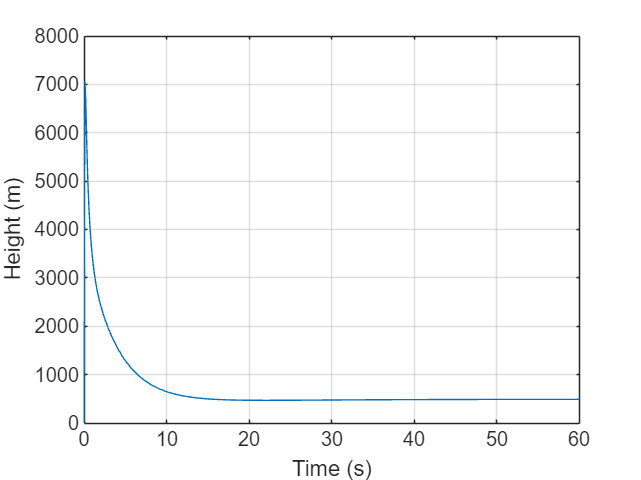


figure;
plot(t_out, y_out(:,2));
ylabel('Height (m)');
xlabel('Time (s)'); grid on;